# Introducción al análisis funcional

## Métricas

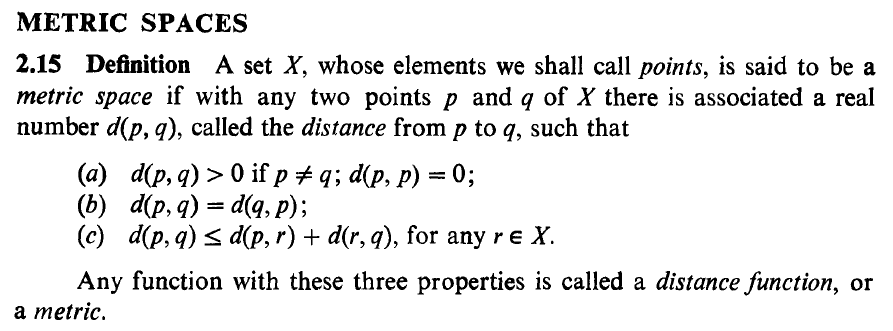

## Normas


$$\left|\right|\cdot \left|\right|\to R$$


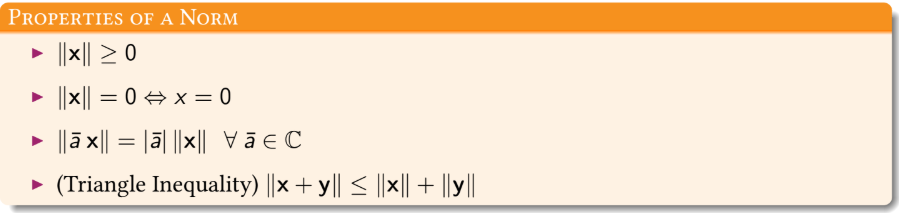

Ejemplo ($x\in R$)


$$\left|\right|x\left|\right|=\left|x\right|$$


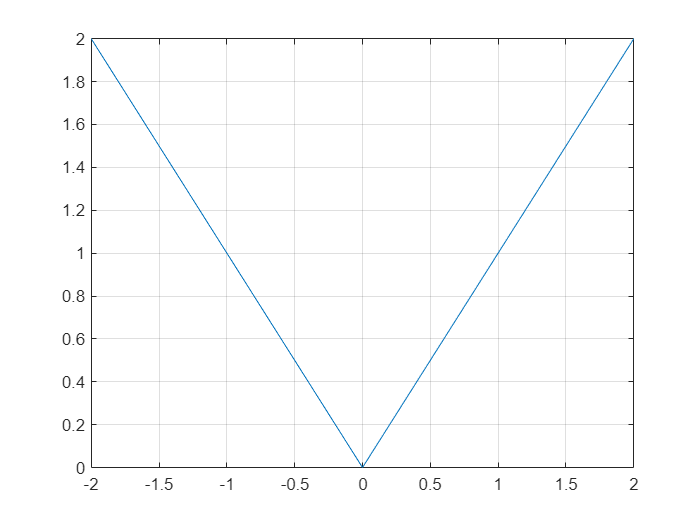

figure()
clf
x=-2:0.01:2;
plot(x,abs(x))
grid on

### Normas en espacios vectoriales


$$\mathit{\mathbf{x}}=\left\lbrace x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right\rbrace \in R^n$$



$$\begin{array}{l}
\left|\right|x\left|{\left|\right.}_1 =\sum_{i=1}^n \left|x_i \right|\right.\\
\left|\right|x\left|{\left|\right.}_2 =\sqrt{\sum_{i=1}^n x_i^2 }\right.\\
\left|\right|x\left|{\left|\right.}_p =\sqrt[p]{\sum_{i=1}^n \left|x_i^{\;} {\left|\right.}^p \right.}\right.\\
\left|\left|x\right|{\left|\right.}_{\infty } =\max_{i\in \left\lbrack 1,n\right\rbrack } {\left|x\right.}_i \right|
\end{array}$$


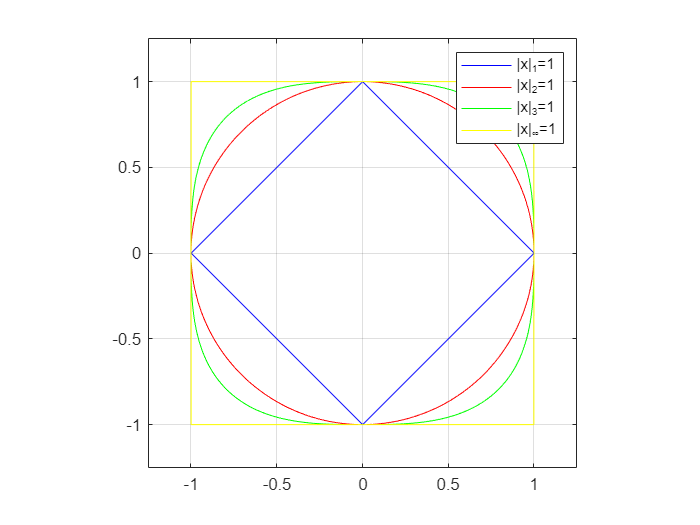

showLNorms()

### Normas en espacios funcionales

$x\left(t\right)$es una función

$\left|\right|x\left(t\right)\left|{\left|\right.}_1 =\int_{-\infty }^{\infty } \left|x\left(t\right)\right|\textrm{dt}\right.$    Norma L1 (si $\left|\right|x\left(t\right)\left|{\left|\right.}_1 <\infty \right.$ entonces $x\left(t\right)$ es absolutamente integrable)

$\left|\right|x\left(t\right)\left|{\left|\right.}_2 =\sqrt[2]{\int_{-\infty }^{\infty } \left|x\left(t\right){\left|\right.}^2 \textrm{dt}\right.}\right.$    Norma L2 (si $\left|\right|x\left(t\right)\left|{\left|\right.}_2 <\infty \right.$ entonces $x\left(t\right)$es una señal de energía)

$\left|\right|x\left(t\right)\left|{\left|\right.}_p =\sqrt[p]{\int_{-\infty }^{\infty } \left|x\left(t\right){\left|\right.}^p \textrm{dt}\right.}\right.$    Norma LP

$\left|\right|x\left(t\right)\left|{\left|\right.}_{\infty } =\sup_{t\in R} \right|x\left(t\right)\left|\right.$    Norma L$\infty$ (si $\left|\right|x\left(t\right)\left|{\left|\right.}_{\infty } <\infty \right.$ entonces $x\left(t\right)$ es acotada)

además, si $\left|\right|x\left(t\right)\left|{\left|\right.}_1 <\infty \right.$ y $\left|\right|x\left(t\right)\left|{\left|\right.}_{\infty } <\infty \right.$ entonces $\left|\right|x\left(t\right)\left|{\left|\right.}_2 <\infty \right.$

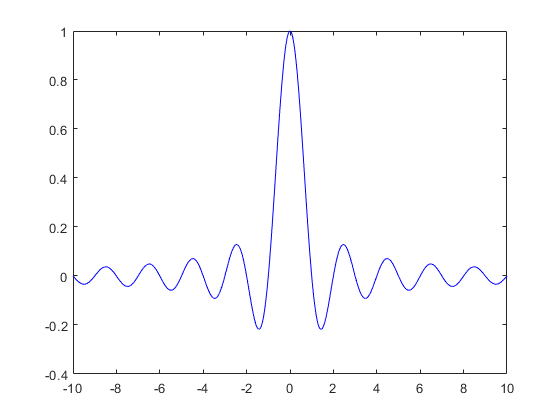

figure()
clf
t = -10:0.01:10;
plot(t,sinc(t),'b')

## Ortogonalidad

### Producto interno entre vectores

Si $\mathit{\mathbf{x}}$ y $\mathit{\mathbf{y}}$ son vectores en $R^n$


$$\left\langle \mathit{\mathbf{x}},\mathit{\mathbf{y}}\right\rangle =\sum_{i=1}^n x_i y_i$$


si $\left\langle \mathit{\mathbf{x}},\mathit{\mathbf{y}}\right\rangle =0$ se dice que $\mathit{\mathbf{x}}$ y $\mathit{\mathbf{y}}$ son vectores **ortogonales**

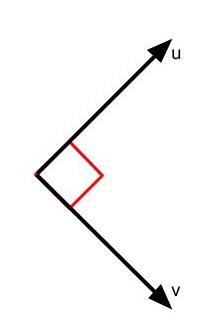

Si se tienen $n$ vectores ortogonales, es posible describir todo $R^n$ como una combinación lineal de estos.

### Producto interno entre funciones

Si $x\left(t\right)$ y $y\left(t\right)$ son funciones definidas en un intervalo $\left\lbrack a,b\right\rbrack$


$$\left\langle x\left(t\right),y\left(t\right)\right\rangle =\int_a^b x\left(t\right)y\left(t\right)\textrm{dt}$$


si $\left\langle x\left(t\right),y\left(t\right)\right\rangle =0$ se dice que $x\left(t\right)$ y $y\left(t\right)$ en el intervalo $\left\lbrack a,b\right\rbrack$ son funciones **ortogonales **en dicho intervalo $x\left(t\right)\bot y\left(t\right)$

$\textrm{sen}\left(t\right)$ y $\cos \left(t\right)$ son ortogonales en el intervalo $\left\lbrack -\pi ,\pi \right\rbrack$


$$\left\langle \textrm{sen}\left(t\right),\cos \left(t\right)\right\rangle =\int_{-\pi }^{\pi } \textrm{sen}\left(t\right)\cos \left(t\right)\textrm{dt}=0$$


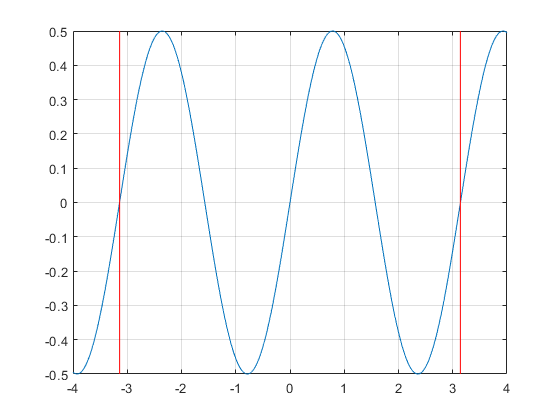

t=-2*pi:0.001:2*pi;
figure
clf
plot(t,sin(t).*cos(t))
grid on
xlim([-4,4])
ylim([-0.5,0.5])
hold on
plot([-pi, -pi, pi, pi], [-1, 1, 1, -1], 'r')

Un conjunto de funciones $\Phi$ se dice ortogonal si $\forall \phi_n ,\phi_m \in \Phi ,\left\langle \phi_n \left(t\right),\phi_m \left(t\right)\right\rangle =0$ para todo $n\not= m$.

Por ejemplo:

El conjunto de todas las fuciones $\delta \left(t-\tau \right)$ es ortogonal.

$\delta \left(t-\tau_1 \right)$ y $\delta \left(t-\tau_2 \right)$ son ortogonales entre si en el intervalo $\left(-\infty ,\infty \right)$ $\forall \tau_1 \not= \tau_2$ 


$$\left\langle \delta \left(t-\tau_1 \right),\delta \left(t-\tau_2 \right)\right\rangle =\int_{-\infty }^{\infty } \delta \left(t-\tau_1 \right)\delta \left(t-\tau_2 \right)\textrm{dt}=0$$


# Series de Fourier

Video recomendado: https://www.youtube.com/watch?v=r6sGWTCMz2k

## Serie generalizada de Fourier

Se puede reconstruir cualquier señal arbitraria sobre el intervalo $\left\lbrack a,b\right\rbrack$ a partir de una suma infinita de funciones $\phi_n \left(t\right)$ ortogonales entre si (en el intervalo):


$$x\left(t\right)=\sum_{n=0}^{\infty } c_n \phi_n \left(t\right)$$


donde $c_n$ puede ser hallado a partir de:


$$c_n =\frac{\left\langle x\left(t\right),\phi_n \left(t\right)\right\rangle }{\left\langle \phi_n \left(t\right),\phi_n \left(t\right)\right\rangle }=\frac{\int_a^b x\left(t\right)\phi_n \left(t\right)\textrm{dt}}{\int_a^b \phi_n^2 \left(t\right)\textrm{dt}}$$


## Serie de Fourier

Tenemos que las señales el conjunto de las señales$\left\lbrace \textrm{sen}\left(\omega_0 t\right),\textrm{sen}\left({2\omega }_0 t\right),\textrm{sen}\left({3\omega }_0 t\right),\ldotp \ldotp \ldotp \right\rbrace \cup \left\lbrace \cos \left(\omega_0 t\right),\cos \left({2\omega }_0 t\right),\cos \left({3\omega }_0 t\right),\ldotp \ldotp \ldotp \right\rbrace$ es **ortogonal, **por lo tanto, podemos escribir cualquier señal (que cumpla las condiciones de dirichlet) como una combinación de elementos de estos conjuntos.

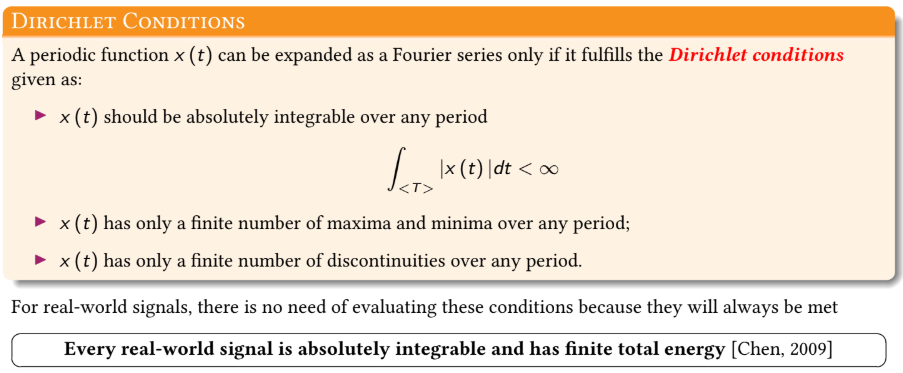

### Serie de Fourier para tiempo continuo (CTFS)

En particular, para las funciones periódicas $x\left(t\right)$ con frecuencia fundamental $\omega_0$ se puede escribir la función como:

$x\left(t\right)=a_0 +\sum_{k=1}^{\infty } a_k \cos \left(k\omega_0 t\right)+b_k \sin \left(k\omega_0 t\right)$            Ecuación de síntesis

donde los coeficientes correspondientes se obtienen a partir de:


$$a_0 =\frac{1}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{dt}=\frac{{\left\langle x\left(t\right),1\right\rangle }_{\left\langle T\right\rangle } }{\left|\right|1\left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$$


$a_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\cos \left(k\omega_0 t\right)\textrm{dt}=\frac{{\left\langle x\left(t\right),\cos \left(k\omega_0 t\right)\right\rangle }_{\left\langle T\right\rangle } }{\left|\right|\cos \left(k\omega_0 t\right)\left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$                Ecuaciones de análisis


$$b_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{sen}\left(k\omega_0 t\right)\textrm{dt}=\frac{{\left\langle x\left(t\right),\textrm{sen}\left(k\omega_0 t\right)\right\rangle }_{\left\langle T\right\rangle } }{\left|\right|\textrm{sen}\left(k\omega_0 t\right)\left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$$


Ejemplo:

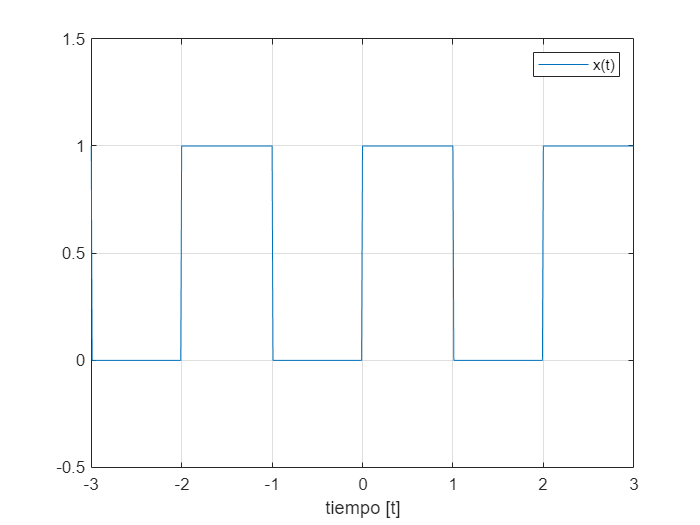

t = -3:0.01:3;
x = (mod(t,2)<=1);
figure()
clf
plot(t,x)
ylim([-0.5,1.5])
xlabel('tiempo [t]')
legend({'x(t)'})
grid on


$$x\left(t\right)=u\left(t\right)-u\left(t-1\right),\;0\le t<2$$



$$\omega_0 =\frac{2\pi }{T}=\pi \left\lbrack \frac{\textrm{rad}}{s}\right\rbrack$$



$$\begin{array}{l}
a_0 =\frac{1}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{dt}\\
\;\;\;\;=\frac{1}{2}\int_0^2 x\left(t\right)\textrm{dt}\\
\;\;\;\;=\frac{1}{2}\int_0^2 u\left(t\right)-u\left(t-1\right)\textrm{dt}\\
\;\;\;\;=\frac{1}{2}\int_0^1 \textrm{dt}\\
\;\;\;\;=\frac{1}{2}
\end{array}$$



$$\begin{array}{l}
a_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\cos \left(k\omega_0 t\right)\textrm{dt}\\
\;\;\;\;=\frac{2}{2}\int_0^2 \left(u\left(t\right)-u\left(t-1\right)\right)\cos \left(k\pi t\right)\textrm{dt}\\
\;\;\;\;=\int_0^1 \cos \left(k\pi t\right)\textrm{dt}\\
\;\;\;\;={\left(\frac{\textrm{sen}\left(k\pi t\right)}{k\pi }\right)}_0^1 \\
\;\;\;\;=\left(\frac{\textrm{sen}\left(k\pi \right)}{k\pi }-0\right)\\
\;\;\;\;=\textrm{senc}\left(k\pi \right)
\end{array}$$



$$\begin{array}{l}
b_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{sen}\left(k\omega_0 t\right)\textrm{dt}\\
\;\;\;\;=\frac{2}{2}\int_0^2 \left(u\left(t\right)-u\left(t-1\right)\right)\textrm{sen}\left(k\pi t\right)\textrm{dt}\\
\;\;\;\;=\int_0^1 \textrm{sen}\left(k\pi t\right)\textrm{dt}\\
\;\;\;\;={\left(-\frac{\cos \left(k\pi t\right)}{k\pi }\right)}_0^1 \\
\;\;\;\;=\left(-\frac{\cos \left(k\pi \left(1\right)\right)}{k\pi }+\frac{\cos \left(k\pi \left(0\right)\right)}{k\pi }\right)\\
\;\;\;\;=\frac{1}{\pi k}\left(1-\cos \left(k\pi \right)\right)\\
\;\;\;\;=\frac{2}{\pi k}{\textrm{sen}}^2 \left(k\frac{\pi }{2}\right)
\end{array}$$


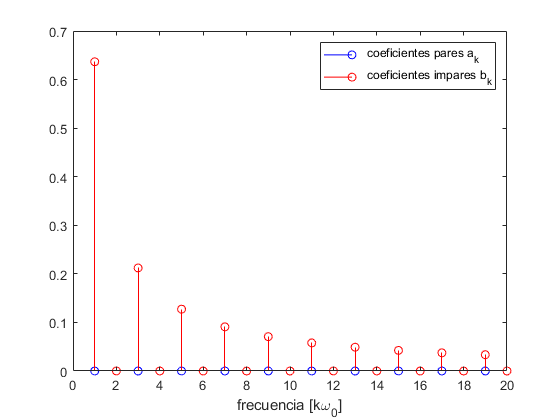

k = 1:20;
omega0 = pi;
a0 = 1/2;
ak = 0*sinc(k*pi);
bk = (2./(pi.*k)).*(sin(k*pi/2).^2);
figure()
clf
stem(k,ak,'b')
hold on
stem(k,bk,'r')
legend({'coeficientes pares a_k','coeficientes impares b_k'})
xlabel('frecuencia [k\omega_0]')

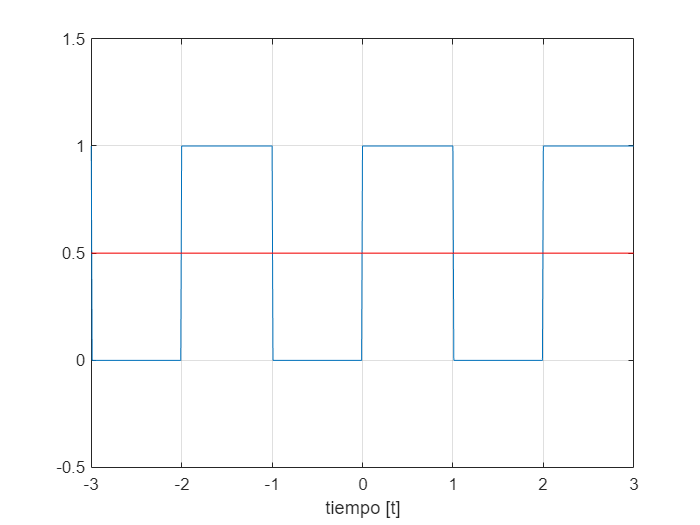

xe = a0*ones(1,length(t));
figure
clf
plot(t,x)
ylim([-0.5,1.5])
hold on
grid on
plot(t,xe,'r')
xlabel('tiempo [t]')

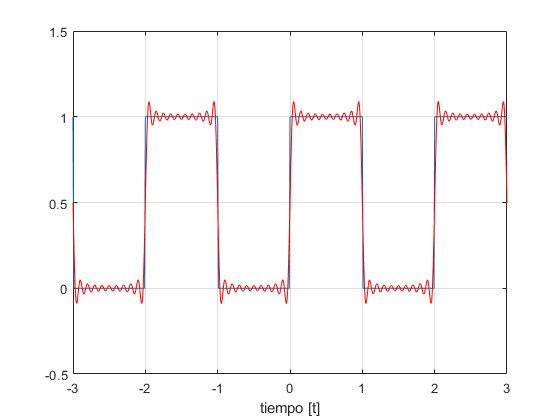

for i = 1:length(k)
    xe = xe + ak(i)*cos(i*omega0*t) + bk(i)*sin(i*omega0*t);
    clf
    plot(t,x)
    ylim([-0.5,1.5])
    hold on
    grid on
    plot(t,xe,'r')
    xlabel('tiempo [t]')
    pause( )
end

#### Representaciones alternativas

Las señales sinusoidales se pueden representar de distintas formas $\sin \left(t\right)=\cos \left(t-\frac{\pi }{2}\right)=\frac{1}{2j}\left(e^{\textrm{jt}} -e^{-\textrm{jt}} \right)$esto conlleva a que las series de fourier también se puedan representar de maneras alternativas a la anteriormente presentada que es llamada **forma trigonométrica, **estas formas alternativas son la **forma de amplitud y fase**:


$$x\left(t\right)=a_0 +\sum_{k=0}^{\infty } A_k \cos \left(k\omega_0 t+\phi_k \right)$$


donde:


$$a_0 =\frac{1}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{dt}$$



$$a_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\cos \left(k\omega_0 t\right)\textrm{dt}=\frac{{\left\langle x\left(t\right),\cos \left(k\omega_0 t\right)\right\rangle }_{\left\langle T\right\rangle } }{\left|\right|\cos \left(k\omega_0 t\right)\left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$$



$$b_k =\frac{2}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)\textrm{sen}\left(k\omega_0 t\right)\textrm{dt}=\frac{{\left\langle x\left(t\right),\textrm{sen}\left(k\omega_0 t\right)\right\rangle }_{\left\langle T\right\rangle } }{\left|\right|\textrm{sen}\left(k\omega_0 t\right)\left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$$



$$A_k =\sqrt{a_k^2 +b_k^2 }$$



$$\phi_k =-\textrm{atan}\left(\frac{b_k }{a_k }\right)=-\textrm{atan2}\left(b_k ,a_k \right)$$


y la **forma exponencial:**


$$x\left(t\right)=\sum_{k=-\infty }^{\infty } \bar{c_k } e^{j{k\omega }_0 t}$$


donde:


$$\bar{c_k } =\frac{1}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)e^{-\textrm{jk}\omega_0 t} \textrm{dt}=\frac{{\left\langle x\left(t\right),e^{-j{k\omega }_0 t} \right\rangle }_{\left\langle T\right\rangle } }{\left|\right|e^{-j{k\omega }_0 t} \left|{\left|\right.}_{\left\langle T\right\rangle }^2 \right.}$$



$$\bar{c_k } =\frac{a_k -{\textrm{jb}}_k }{2}$$


#### Tabla de equivalencias

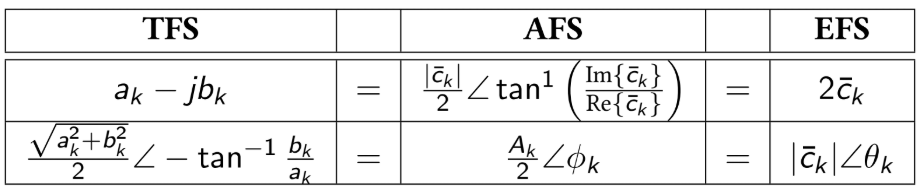

Por ejemplo:

Si tomamos los coeficientes de la forma trigonométrica obtenidos en para $x\left(t\right)=u\left(t\right)-u\left(t-1\right),\;0\le t<2$

    
$$x\left(t\right)=a_0 +\sum_{k=1}^{\infty } a_k \cos \left(k\omega_0 t\right)+b_k \sin \left(k\omega_0 t\right)$$


    con

    
$$a_0 =\frac{1}{2}$$


    
$$a_k =\textrm{senc}\left(k\pi \right)=0$$


    
$$b_k =\frac{2}{\pi k}{\textrm{sen}}^2 \left(k\frac{\pi }{2}\right)$$


podemos obtener los coeficientes de la forma exponencial:

    
$$x\left(t\right)=\sum_{k=-\infty }^{\infty } x\left(t\right)\bar{c_k } e^{j{k\omega }_0 t}$$


    con

    
$$\bar{c_k } =\frac{a_k -{\textrm{jb}}_k }{2}=\frac{1}{2}\textrm{senc}\left(k\pi \right)-\frac{j}{\pi k}{\textrm{sen}}^2 \left(\frac{k\pi }{2}\right)$$


y los coeficientes de la forma de amplitud y fase (El desarrollo paso a paso se encuentra en el Apéndice I):

    
$$x\left(t\right)=a_0 +\sum_{n=0}^{\infty } A_k \cos \left(k\omega_0 t+\phi_k \right)$$


    con

    
$$A_k =\sqrt{a_k^2 +b_k^2 }$$


    
$$\phi_k =-\textrm{atan}\left(\frac{b_k }{a_k }\right)$$


#### Espectros de magnitud y fase

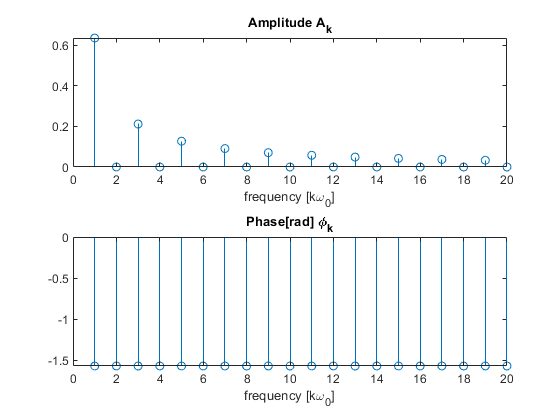

k = 1:20;
a0 = 1/2;
Ak = sqrt(ak.^2+bk.^2);
phik = -atan2(bk,ak);
figure
clf
subplot(2,1,1)
stem(k,Ak)
title('Amplitude A_k')
xlabel('frequency [k\omega_0]')
subplot(2,1,2)
stem(k,phik)
title('Phase[rad] \phi_k')
xlabel('frequency [k\omega_0]')

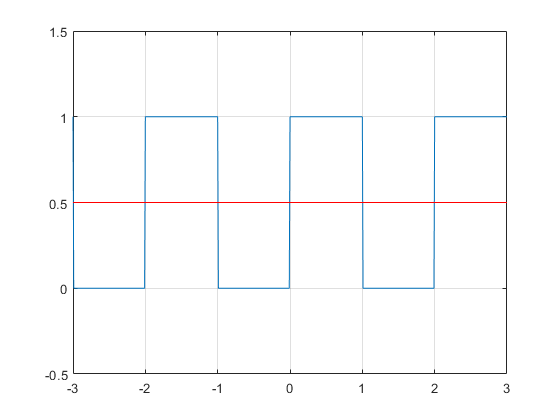

xe = a0*ones(1,length(t));
figure
clf
plot(t,x)
ylim([-0.5,1.5])
hold on
grid on
plot(t,xe,'r')

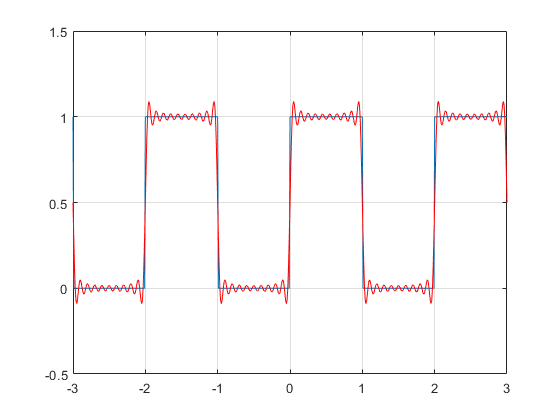

for i = 1:length(k)
    xe = xe + Ak(i)*cos(i*omega0*t+phik(i));
    clf
    plot(t,x)
    ylim([-0.5,1.5])
    hold on
    grid on
    plot(t,xe,'r')
    pause(0.5)
end

### Simetrías

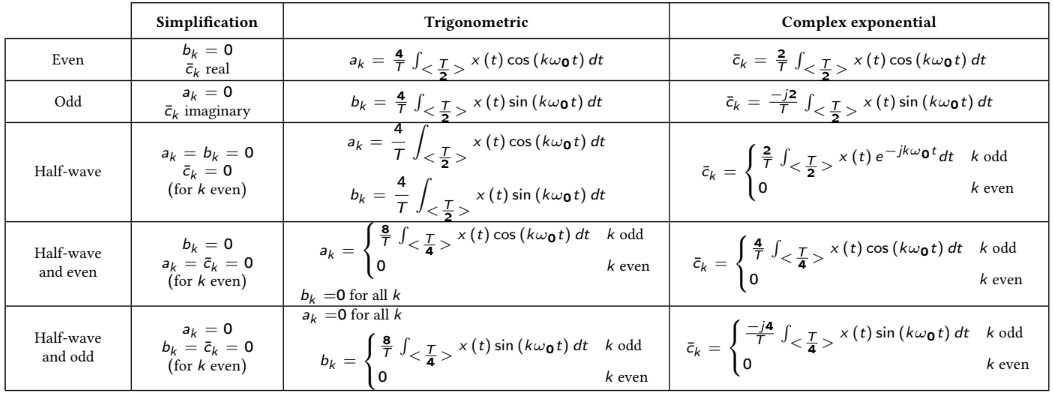

### Propiedades

Sean $x\left(t\right)$ y $y\left(t\right)$ dos funciones periódicas **con el mismo periodo fundamental **y sean $a$ y $b$ escalares, se tienen las siguientes relaciones.

**Linealidad**


$$a\;x\left(t\right)+b\;y\left(t\right)\overset{\textrm{FS}}{\to} a\;\bar{\alpha_k } +b\bar{{\;\beta }_k }$$


**Desfase en el tiempo**


$$x\left(t-t_o \right)\overset{\textrm{FS}}{\to} e^{-j\omega_0 t_0 } \bar{\alpha_k }$$


**Inversión en el tiempo**


$$x\left(-t\right)\overset{\textrm{FS}}{\to} \bar{\alpha_{-k} }$$


**Escalado en el tiempo**


$$x\left(\textrm{at}\right)\overset{\textrm{FS}}{\to} \bar{\alpha_k }$$


Nota: esto no significa que las representaciones sean idéndicas ya que si bien los coeficientes son los mismos, la frecuencia fundamental sobre la cuál se definen las expresiones varía.

**Derivación**


$$\frac{d}{\textrm{dt}}x\left(t\right)\overset{\textrm{FS}}{\to} \left(\textrm{jk}\omega_o \right)\bar{\alpha_k }$$


**Integración**


$$\int_{-\infty }^t x\left(t\right)\overset{\textrm{FS}}{\to} \frac{1}{\textrm{jk}\omega_0 }\bar{\alpha_k }$$


### Serie de Fourier para tiempo discreto (DTFS)

Las funciones periódicas discretas $x\left\lbrack n\right\rbrack =x\left\lbrack n+N\right\rbrack$ con frecuencia fundamental $\Omega_0 =\frac{2\pi }{N}$ también se pueden escribir suma de funciones senoidales según:


$$x\left\lbrack n\right\rbrack =\sum_{k=0}^{N-1} \bar{c_k } e^{\textrm{jk}\Omega_0 n}$$


donde los coeficientes correspondientes se obtienen a partir de:


$$\bar{c_k } =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{jk}\Omega_0 n}$$


Ejemplo:

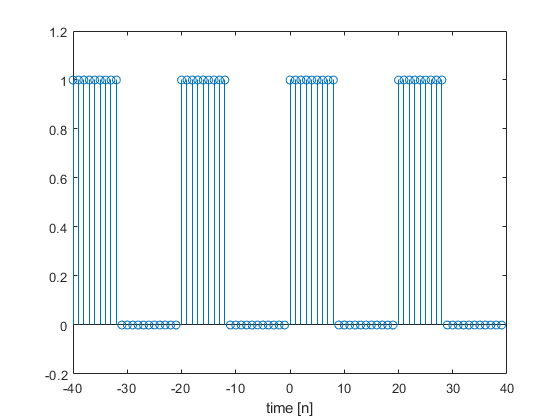

figure
clf
N = 20;
k=-2*N:2*N-1;
x = @(n) (mod(n,N)<N/2-1);
stem(k,x(k))
ylim([-0.2,1.2])
xlabel('time [n]')


$$x\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-9\right\rbrack ,0\le n<20$$



$$\Omega_0 =\frac{2\pi }{N}=\frac{\pi }{10}$$



$$\bar{c_k } =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{jk}\Omega_0 n}$$



$$\begin{array}{l}
\bar{c_k } =\frac{1}{20}\sum_{n=0}^{20-1} \left(u\left\lbrack n\right\rbrack -u\left\lbrack n-9\right\rbrack \right)e^{-\textrm{jk}\frac{\pi }{10}n} \\
\;\;\;\;=\frac{1}{20}\sum_{n=0}^8 e^{-\textrm{jk}\frac{\pi }{10}n} \\
\;\;\;\;=\frac{1}{20}\sum_{n=0}^8 {\left(e^{-\textrm{jk}\frac{\pi }{10}} \right)}^n 
\end{array}$$


Esto parece una serie geométrica de la forma $\sum_{n=0}^N r^n =\frac{1-r^{N+1} }{1-r}$ sin embargo, esto solo aplica para $r\not= 1$, entonces debemos analizar $e^{-\textrm{jk}\frac{\pi }{10}}$


$$e^{-\textrm{jk}\frac{\pi }{10}} =\left\lbrace \begin{array}{cc}
1 & \textrm{si}\;k=0,20,40,\ldotp \ldotp \ldotp \\
e^{-\textrm{jk}\frac{\pi }{10}}  & \textrm{si}\;k\not= 0,20,40,\ldotp \ldotp \ldotp 
\end{array}\right.$$


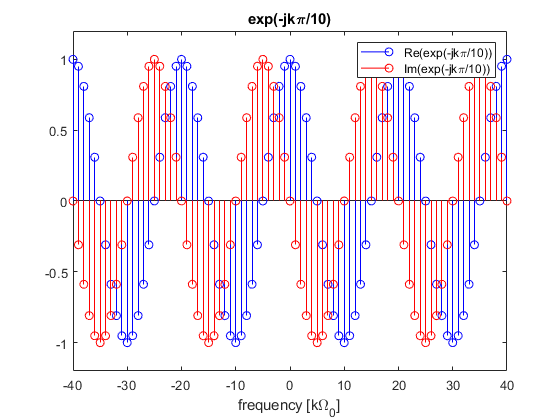

figure
clf
k = -40:40;
f = @(k) exp(-1j*k*pi/10);
stem(k,real(f(k)),'b');
hold on
stem(k,imag(f(k)),'r');
legend({'Re(exp(-jk\pi/10))', 'Im(exp(-jk\pi/10))'})
title('exp(-jk\pi/10)')
ylim([-1.2,1.2])
xlabel('frequency [k\Omega_0]')

Entonces la serie queda de la forma:


$$\;\;\;\;=\left\lbrace \begin{array}{cc}
\frac{1}{20}\sum_{n=0}^8 1^n  & \textrm{si}\;k=0,20,40,\ldotp \ldotp \ldotp \\
\frac{1}{20}\sum_{n=0}^8 {\left(e^{-\textrm{jk}\frac{\pi }{10}} \right)}^n  & \textrm{si}\;k\not= 0,20,40,\ldotp \ldotp \ldotp 
\end{array}\right.$$



$$\;\;\;\;=\left\lbrace \begin{array}{cc}
\frac{1}{20}\sum_{n=0}^8 1 & \textrm{si}\;k=0,20,40,\ldotp \ldotp \ldotp \\
\frac{1}{20}\left(\frac{1-{\left(e^{-\textrm{jk}\frac{\pi }{10}} \right)}^9 }{1-\left(e^{-\textrm{jk}\frac{\pi }{10}} \right)}\right) & \textrm{si}\;k\not= 0,20,40,\ldotp \ldotp \ldotp 
\end{array}\right.$$



$$\;=\left\lbrace \begin{array}{cc}
\frac{9}{20} & \textrm{si}\;k=0,20,40,\ldotp \ldotp \ldotp \\
\frac{1}{20}\left(\frac{1-e^{-\textrm{jk}\frac{9\pi }{10}} }{1-e^{-\textrm{jk}\frac{\pi }{10}} }\right) & \textrm{si}\;k\not= 0,20,40,\ldotp \ldotp \ldotp 
\end{array}\right.$$


Esta ya sería una respuesta correcta, sin embargo se puede escribir de una manera más fácil de visualizar considerando que:


$$1-e^{\textrm{jx}} =1-e^{\frac{\textrm{jx}}{2}+\frac{\textrm{jx}}{2}} =1-e^{\frac{\textrm{jx}}{2}} e^{\frac{\textrm{jx}}{2}} =e^{\frac{\textrm{jx}}{2}} \left(e^{-\frac{\textrm{jx}}{2}} -e^{\frac{\textrm{jx}}{2}} \right)=e^{\frac{\textrm{jx}}{2}} \left(-2\textrm{jsin}\left(\frac{x}{2}\right)\right)$$


Entonces;


$$\frac{1-e^{-\textrm{jk9}\frac{\pi }{10}} }{1-e^{-\textrm{jk}\frac{\pi }{10}} }=\frac{e^{-\textrm{jk}\frac{9\pi }{20}} \left(-2\textrm{jsin}\left(k\frac{9\pi }{20}\right)\right)}{e^{-\textrm{jk}\frac{\pi }{20}} \left(-2\textrm{jsin}\left(k\frac{\pi }{20}\right)\right)}=e^{-\textrm{jk}\frac{2\pi }{5}} \left(\frac{\sin \left(k\frac{9\pi }{20}\right)}{\sin \left(k\frac{\pi }{20}\right)}\right)$$


Con lo que la respuesta final puede ser escrita como:


$$=\left\lbrace \begin{array}{cc}
\frac{9}{20} & \textrm{si}\;k=0,20,40,\ldotp \ldotp \ldotp \\
\frac{e^{-\textrm{jk}\frac{2\pi }{5}} }{20}\left(\frac{\sin \left(k\frac{9\pi }{20}\right)}{\sin \left(k\frac{\pi }{20}\right)}\right) & \textrm{si}\;k\not= 0,20,40,\ldotp \ldotp \ldotp 
\end{array}\right.$$


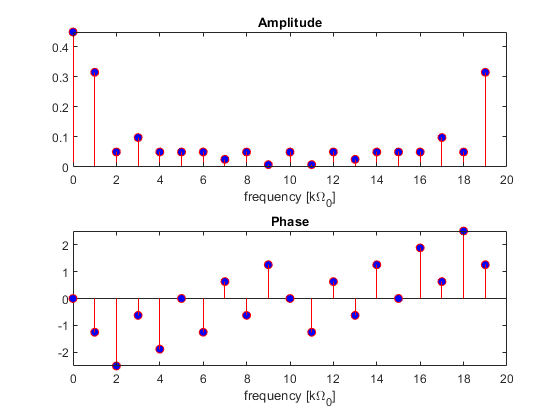

cka = @(k) (1/20)*(exp(-1j*k*2*pi/5))*(sin(k*9*pi/20)/sin(k*pi/20));
Omega0 = 2*pi/N;
i = 1;
ckn = zeros([1 N]);
n = 0:N-1;
k_min = 0;
k_max = N-1;
for k= k_min:k_max
    ckn(i) = 1/N*sum(x(n).*exp(-1j*k*Omega0*n));
    i = i+1;
end
figure
clf
subplot(2,1,1)
k = k_min:k_max;
cka_plot = ones([1, k_max-k_min+1]);
for i = 1:length(k)
    if mod(k(i),20)==0
        cka_plot(i) = 9/20;
    else
        cka_plot(i) = cka(k(i));
    end
end
stem(k,abs(ckn),'b','filled')
hold on
stem(k,abs(cka_plot),'r')
title('Amplitude')
xlabel('frequency [k\Omega_0]')
subplot(2,1,2)
stem(k,angle(ckn),'b','filled')
hold on
stem(k,angle(cka_plot),'r')
title('Phase')
xlabel('frequency [k\Omega_0]')

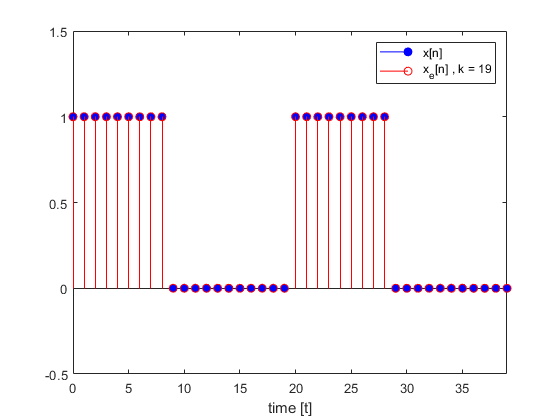

n = 0:3*N-1;
xe = zeros([1 length(n)]);
k = k_min:k_max;
figure
clf
for i =1:1:length(ckn)
    xe = xe + ckn(i)*exp(1j*k(i)*Omega0*n);
    stem(n,x(n),'b','filled')
    hold on
    stem(n,real(xe),'r')
    legend({'x[n]', ['x_e[n] , k = ' num2str(k(i))]})
    xlim([0 2*N-1])
    ylim([-0.5 1.5])
    xlabel('time [t]')
    hold off
    pause( )
end

## Transformada de Fourier

Si se tiene una señal que no sea periódica, esta se puede representar como una sumatoria de funciones senoidales a partir de considerar una función no periódica como una función con periodo infinito siempre y cuando esta sea absolutamente integrable (o sumable según el dominio).

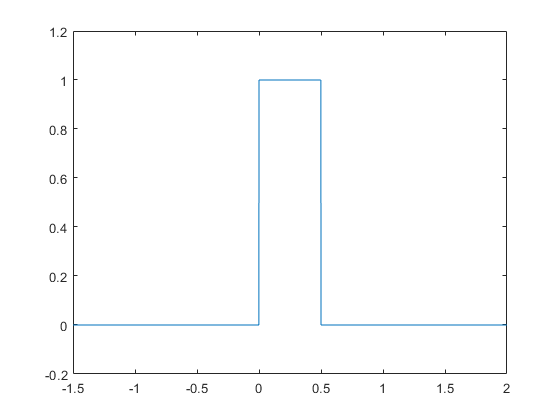

u = @(t) t>=0;
t = -5:0.001:5;
figure
plot(t,u(t)-u(t-0.5));
% plot(t,2*t.*(u(t)-u(t-0.5)));
ylim([-0.2,1.2])
xlim([-1.5,2])

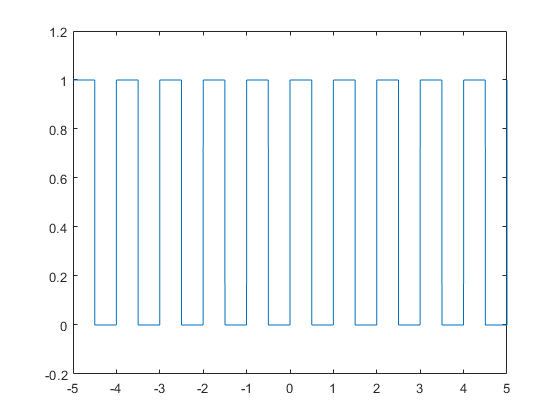

figure
% subplot(1,2,1)
pulses = @(t,T0,dc) (mod(t,T0)<=T0*dc);
%rpulses = @(t,T0,dc) (mod(t,T0).*(mod(t,T0)<=T0*dc));
plot(t,pulses(t,1,.5));
ylim([-0.2,1.2])


$$x\left(t\right)=u\left(t\right)-u\left(t-0\ldotp 5\right),0\le x\le T_0$$


El desarrollo de estos coeficientes se encuentra en el Apéndice II


$$\bar{c_k } =\frac{1}{T_0 }e^{-j\frac{k\pi }{T_0 }} \textrm{sinc}\left(\frac{k\pi }{T_0 }\right)$$


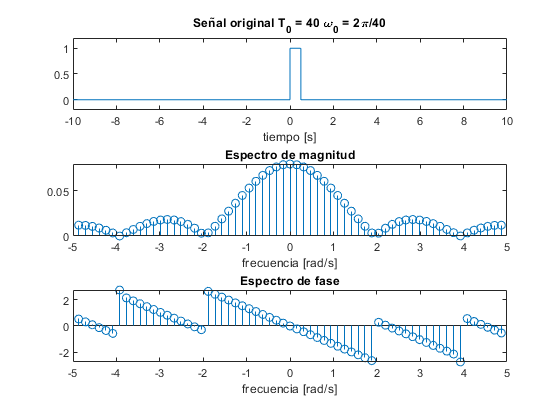

dt = 0.001;
t = -10:dt:10;
omega_max = 5;
figure
clf
for i = 1:1:40
    T0 = i;
    x = @(t) pulses(t,T0,1/(2*i));
    omega0 = 2*pi/T0;
    k_max = 100;
    ck = CEFS(x, omega0, k_max);
    mag = abs(ck);
    ang = angle(ck);
    k = omega0*(-k_max:k_max);
    subplot(3,1,1)
    plot(t,x(t))
    title(['Señal original T_0 = ' num2str(T0) ' \omega_0 = 2\pi/' num2str(T0)])
    xlabel('tiempo [s]')
    ylim([-0.2,1.2])
    subplot(3,1,2)
    stem(k,mag)
    xlim([-omega_max,omega_max])
    title('Espectro de magnitud')
    xlabel('frecuencia [rad/s]')
    subplot(3,1,3)
    stem(k,ang)
    xlim([-omega_max,omega_max])
    title('Espectro de fase')
    xlabel('frecuencia [rad/s]')
    pause( )
end

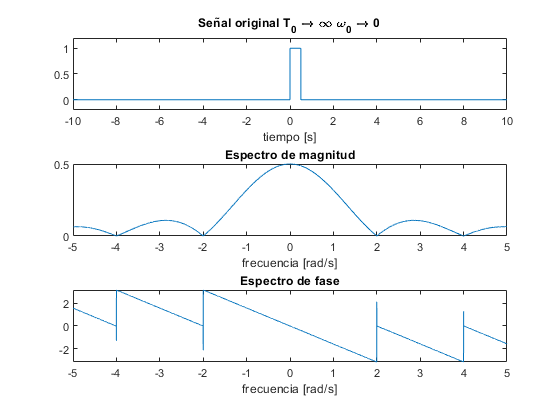

u = @(t) (t>=0);
x = @(t) u(t)-u(t-0.5);
% x = @(t) 2*t.*(u(t)-u(t-0.5));
domega = 0.001;
omega = -omega_max:domega:omega_max;
X = CTFourierTransform(x(t),t,2*pi*omega,dt);
mag = abs(X);
ang = angle(X);
subplot(3,1,1)
plot(t,x(t))
title('Señal original T_0 \rightarrow \infty \omega_0 \rightarrow 0')
xlabel('tiempo [s]')
ylim([-0.2,1.2])
subplot(3,1,2)
plot(omega,mag)
title('Espectro de magnitud')
xlabel('frecuencia [rad/s]')
subplot(3,1,3)
plot(omega,ang)
title('Espectro de fase')
xlabel('frecuencia [rad/s]')

### Transformada de Fourier para tiempo continuo (CTFT)

En particular si $x\left(t\right)$ es una función continua no periódica, se puede obtener su transformada de Fourier a partir de la ecuación de análisis:


$$X\left(\omega \right)=F\left\lbrace x\left(t\right)\right\rbrace =\int_{-\infty }^{\infty } x\left(t\right)e^{-j\omega t} \textrm{dt}$$


y es posible reconstruir la señal a partir de la ecuación de síntesis:


$$x\left(t\right)=F^{-1} \left\lbrace X\left(\omega \right)\right\rbrace =\frac{1}{2\pi }\int_{-\infty }^{\infty } X\left(\omega \right)e^{j\omega t} d\omega$$


**Ejemplo:**


$$x\left(t\right)=u\left(t\right)-u\left(t-0\ldotp 5\right)$$



$$X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-j\omega t} \textrm{dt}$$



$$\begin{array}{l}
X\left(\omega \right)=\int_{-\infty }^{\infty } \left(u\left(t\right)-u\left(t-0\ldotp 5\right)\right)e^{-j\omega t} \textrm{dt}\\
X\left(\omega \right)=\int_0^{0\ldotp 5} e^{-j\omega t} \textrm{dt}\\
X\left(\omega \right)=-\frac{1}{j\omega }{\left(e^{-j\omega t} \right)}_{t=0}^{t=0\ldotp 5} \\
X\left(\omega \right)=-\frac{1}{j\omega }\left(e^{-j\frac{\omega }{2}} -1\right)\\
X\left(\omega \right)=\frac{1}{j\omega }\left(1-e^{-j\frac{\omega }{2}} \right)
\end{array}$$


Por visualización usamos la identidad $1-e^{-\textrm{jx}} =e^{-j\frac{x}{2}} \left(e^{j\frac{x}{2}} -e^{-j\frac{x}{2}} \right)=e^{-j\frac{x}{2}} 2\textrm{jsin}\left(\frac{x}{2}\right)$


$$\begin{array}{l}
X\left(\omega \right)=\frac{2}{\omega }e^{-j\frac{\omega }{4}} \sin \left(\frac{\omega }{4}\right)\\
X\left(\omega \right)=\frac{1}{2}\frac{4}{\omega }e^{-j\frac{\omega }{4}} \sin \left(\frac{\omega }{4}\right)\\
X\left(\omega \right)={\frac{1}{2}e}^{-j\frac{\omega }{4}} \textrm{sinc}\left(\frac{\omega }{4}\right)
\end{array}$$


#### Transformada de Fourier para funciones periódicas continuas

Las funciones periódicas no cumplen con la condición de absoluta integrabilidad, sin embargo, si se admite la incorporación de funciones de singularidad en las transformadas, es posible escribir las transformadas de Fourier a partir de los coeficientes de las series de Fourier de las mismas según:


$$X\left(\omega \right)=\sum_{k=-\infty }^{\infty } 2\pi \bar{c_k } \delta \left(\omega -k\omega_0 \right)$$



$$\bar{c_k } =\frac{1}{T}\int_{\left\langle T\right\rangle }^{\;} x\left(t\right)e^{-\textrm{jk}\omega_0 t} \textrm{dt}$$


**Identidades útiles**


$$e^{\pm \textrm{jx}} =\cos \left(x\right)\pm \textrm{jsin}\left(x\right)$$



$$\sin \left(x\right)=\frac{e^{\textrm{jx}} -e^{-\textrm{jx}} }{2j}$$



$$\cos \left(x\right)=\frac{e^{\textrm{jx}} +e^{-\textrm{jx}} }{2}$$


### Transformada de Fourier para tiempo discreto (DTFT)

Si tomamos la función $x\left\lbrack n\right\rbrack =r\left\lbrack n\right\rbrack -r\left\lbrack n-9\right\rbrack -9u\left(n-9\right)$ y aplicamos la misma idea del caso continuo (volverla periódica e incrementar ese periodo cada vez más) podremos ver los siguiente:

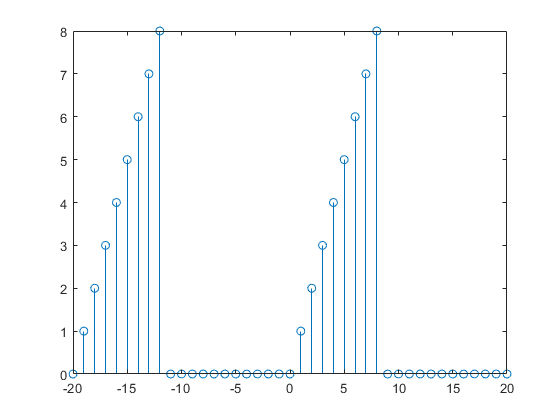

n = -20:20;
figure
clf
rpulses = @(t,T0,dc) (mod(t,T0).*(mod(t,T0)<=T0*dc));
x = @(n) rpulses(n,20,0.4);
stem(n,x(n));

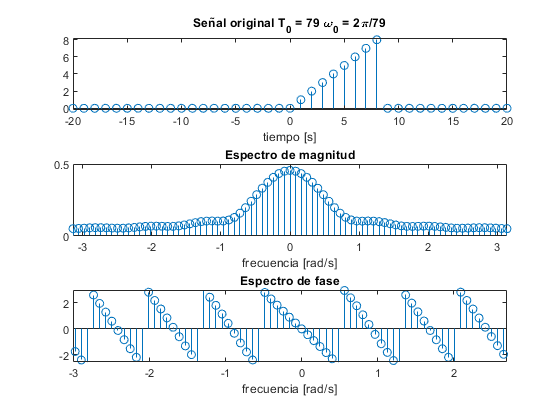

for i = 9:2:80
    T0 = i;
    x = @(n) rpulses(n,i,(8/i));
    omega0 = 2*pi/T0;
    k_max = 100;
    ck = DEFS(x, T0);
    ck = fftshift(ck);
    mag = abs(ck);
    ang = angle(ck);
    k = linspace(-T0/2,T0/2,length(ck))*omega0;
    subplot(3,1,1)
    stem(n,x(n))
    title(['Señal original T_0 = ' num2str(T0) ' \omega_0 = 2\pi/' num2str(T0)])
    xlabel('tiempo [s]')
    ylim([-0.2,8.2])
    subplot(3,1,2)
    stem(k,mag)
    xlim([-pi,pi])
    title('Espectro de magnitud')
    xlabel('frecuencia [rad/s]')
    subplot(3,1,3)
    stem(k,ang)
    xlim([-pi,pi])
    title('Espectro de fase')
    xlabel('frecuencia [rad/s]')
    pause(.1)
end

r = @(t) t.*(t>=0);
x = r(n)-r(n-9)-9*u(n-9);
dOmega = 2*pi/1000;
Omega = -pi:dOmega:pi;
X = DTFourierTransform(x,n,dOmega);
subplot(3,1,1)
stem(n,x)
title('Señal original T_0 \rightarrow \infty \omega_0 \rightarrow 0')
xlabel('tiempo [s]')
ylim([-0.2,8.2])
subplot(3,1,2)
plot(Omega,abs(X))
xlim([-pi,pi])
title('Espectro de magnitud')
xlabel('frecuencia [rad/s]')
subplot(3,1,3)
plot(Omega,angle(X))
xlim([-pi,pi])
title('Espectro de fase')
xlabel('frecuencia [rad/s]')

Es decir que al igual que en el caso continuo, podemos expresar funciones no periodicas absolutamente sumables y de soporte finito a partir de una suma infinita (integral) de funciones senoidales y podemos obtener los coeficientes de esta integral a partir de la ecuación de análisis (transformada directa):


$$X\left(\Omega \right):=\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack e^{-j\Omega n} =F\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace$$


y se puede reconstruir la señal a partir de la ecuación de síntesis (transformada inversa)


$$x\left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{\pi } X\left(\Omega \right)e^{j\Omega n} d\Omega$$


#### ¿Por qué entre $-\pi$ y $\pi$?

En realidad, se puede hacer en cualquier intervalo cerrado de longitud $2\pi$ya que el comportamiento en frecuencia de las series y transformadas de Fourier en tiempo discreto es periódico (la frecuencia fundamental es $\frac{2\pi }{N}$ y se tienen $N$ muestras, de modo que al ser periódica, toda la información está en un intervalo de longitud $2\pi$).

#### Transformada de fourier para funciones periódicas discretas (DTFT)

De manera similar al caso continuo, es posible tener la transformada de Fourier de una función periodica discreta a partir de los coeficientes de su serie de Fourier según:


$$\bar{c_k } =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{jk}\Omega_0 n}$$



$$X\left(\Omega \right)=\sum_{k=0}^{N-1} 2\pi \bar{c_k } \sum_{m=-\infty }^{\infty } \delta \left(\Omega \;-k\Omega_0 -2\pi m\right)$$


#### Transformada discreta de Fourier (DFT)

Dado que la transformada de Fourier para tiempo discreto resulta en una función continua con infinitos puntos entre $-\pi \;$ y $\pi$, no es apropiada para su uso computacional. En su lugar, se suele usar la llamada transformada de Fourier discreta (DFT) tomando una cantidad finita de muestras relevantes de la señal de interés para obtener su representación como serie de Fourier para tiempo discreto "volviendola periódica":


$$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-j\left(\frac{2\pi k}{N}\right)n}$$



$$x\left\lbrack n\right\rbrack =\sum_{n=0}^{N-1} X\left\lbrack k\right\rbrack e^{j\left(\frac{2\pi k}{N}\right)n}$$


El resultado de esto es equivalente a muestrear la transformada de Fourier para tiempo discreto a frecuencias $\frac{2\pi k}{N}$. Según la aplicación esta resolución puede ser muy dispersa, para solucionar esto, es posible añadir un número finito de muestras con valor 0 a la señal como hicimos en el desarrollo de la intuición para obtener más datos (*zero-padding*). 

Véase FFT: https://www.youtube.com/watch?v=h7apO7q16V0

### Propiedades de las transformadas de Fourier

#### Escala en el tiempo


$$x\left(\alpha t\right)\overset{F}{\leftrightarrow} \frac{1}{|\alpha |}X\left(\frac{\omega }{\alpha }\right),\;\;\;\alpha \not= 0$$


#### Corrimiento en el tiempo


$$x\left(t-t_0 \right)\leftrightarrow X\left(\omega \right)e^{-j\omega t_0 }$$


**Nota: **las fases del producto de dos números complejos se suman $z_1 z_2 =r_1 e^{j\theta_1 } r_2 e^{j\theta_2 } =r_1 r_2 e^{j\left(\theta_1 +\theta_2 \right)}$


$$x\left(\alpha \left(t-t_0 \right)\right)\overset{F}{\leftrightarrow} \frac{1}{|\alpha |}X\left(\frac{\omega }{\alpha }\right)e^{-j\omega t_0 }$$


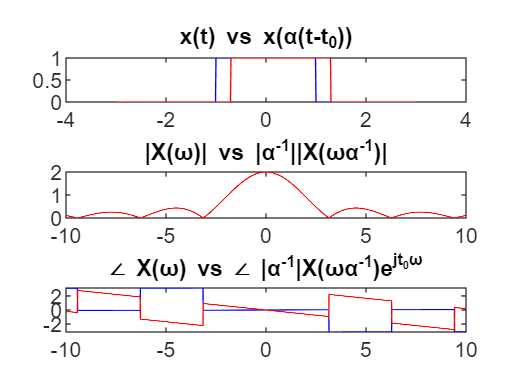

alpha =1;
t0 =0.3;
dt = 0.01;
t = -3:dt:3;
x = @(t) u(t+1) - u(t-1);
%x = @(t) u(t+1) - 0.5*r(t+1) + 0.5*r(t-1);
omega = -10:0.01:10;
X = CTFourierTransform(x(t),t,omega,dt);
Xa = CTFourierTransform(x(alpha*(t-t0)),t,omega,dt);
figure()
subplot(3,1,1)
plot(t,x(t),'b',t,x(alpha*(t-t0)),'r')
title('x(t) vs x({\alpha}(t-t_0))')
subplot(3,1,2)
plot(omega,abs(X),'b',omega,abs(Xa),'r')
title('|X(\omega)| vs |\alpha^{-1}||X({\omega}\alpha^{-1})|')
subplot(3,1,3)
plot(omega,angle(X),'b',omega,angle(Xa),'r')
title('\angle X(\omega) vs \angle |\alpha^{-1}|X({\omega}\alpha^{-1})e^{jt_0\omega}')

#### Dualidad


$$X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-j\omega t} \textrm{dt}$$



$$x\left(t\right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } X\left(\omega \right)e^{j\omega t} d\omega$$


Si hacemos un cambio doble de variable (intercambiamos $t$ y $\omega$)


$$X\left(t\right)=\int_{-\infty }^{\infty } x\left(\omega \right)e^{-\textrm{jt}\omega } d\omega$$



$$x\left(\omega \right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } X\left(t\right)e^{\textrm{jt}\omega } \textrm{dt}$$


#### Ejemplo

Partimos del siguiente resultado:


$$\begin{array}{l}
x\left(t\right)=\delta \left(t\right)\\
X\left(\omega \right)=\int_{-\infty }^{\infty } \delta \left(t\right)e^{-j\omega t} \textrm{dt}=1
\end{array}$$


Esto implica que 


$$x\left(t\right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } \left(1\right)e^{j\omega t} d\omega =\delta \left(t\right)$$


Ahora vamos a obtener


$$x\left(t\right)=e^{j\omega_0 t}$$



$$F\left\lbrace x\left(t\right)\right\rbrace =\int_{-\infty }^{\infty } x\left(t\right)e^{-j\omega t} \textrm{dt}$$



$$F\left\lbrace x\left(t\right)\right\rbrace =\int_{-\infty }^{\infty } e^{j\omega_0 t} e^{-j\omega t} \textrm{dt}=\int_{-\infty }^{\infty } e^{-j\left(\omega -\omega_0 \right)t} \textrm{dt}$$


    Notamos que esta integral, es similar a $x\left(t\right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } \left(1\right)e^{j\omega t} d\omega =\delta \left(t\right)$. Aquí es donde aplicamos el doble cambio de variable:

    
$$\frac{1}{2\pi }\int_{-\infty }^{\infty } \left(1\right)e^{\textrm{jt}\omega } \textrm{dt}=\delta \left(\omega \right)$$


    
$$\int_{-\infty }^{\infty } \left(1\right)e^{-\textrm{jt}\omega } \textrm{dt}=2\pi \delta \left(-\left(\omega -\omega_0 \right)\right)=2\pi \delta \left(\omega -\omega_0 \right)$$


### Respuesta en frecuencia de los sistemas

Tenemos que:


$$y\left(t\right)=x\left(t\right)\ast h\left(t\right)$$


Aplicando la transformada de Fourier:


$$Y\left(\omega \right)=X\left(\omega \right)H\left(\omega \right)$$


De aquí podemos obtener dos resultados últiles:


$$y\left(t\right)=F^{-1} \left\lbrace X\left(\omega \right)H\left(\omega \right)\right\rbrace$$



$$h\left(t\right)=F^{-1} \left\lbrace H\left(\omega \right)\right\rbrace =F^{-1} \left\lbrace \frac{Y\left(\omega \right)}{X\left(\omega \right)}\right\rbrace$$


**Nota:** $H\left(\omega \right)$ se conoce como la respuesta en frecuencia del sistema.

#### Teorema de respuesta en frecuencia:

Sea $H\left(\omega \right)$ es la respuesta en frecuencia del sistema

si aplico $x\left(t\right)=\sin \left(\omega_0 t\right)\to y_{\textrm{ss}} \left(t\right)=\lim_{t\to \infty } y\left(t\right)=\left|H\left(\omega_0 \right)\right|\sin \left(\omega_0 t+\angle H\left(\omega_0 \right)\right)$

# Apéndices

## Apendice I - Coeficientes AF


$$\begin{array}{l}
\phi_k =-\textrm{atan}\left(\frac{b_k }{a_k }\right)\\
\;\;\;\;=-\textrm{atan}\left(\frac{\frac{2}{\pi k}{\textrm{sen}}^2 \left(k\frac{\pi }{2}\right)}{\textrm{senc}\left(k\pi \right)}\right)\\
\;\;\;\;=-\textrm{atan}\left(\frac{2{\textrm{sen}}^2 \left(k\frac{\pi }{2}\right)}{\textrm{sen}\left(k\pi \right)}\right)\\
\;\;\;\;=-\textrm{atan}\left(\frac{2{\textrm{sen}}^2 \left(k\frac{\pi }{2}\right)}{2\textrm{sen}\left(k\frac{\pi }{2}\right)\cos \left(k\frac{\pi }{2}\right)}\right)\\
\;\;\;\;=-\textrm{atan}\left(\frac{\textrm{sen}\left(k\frac{\pi }{2}\right)}{\cos \left(k\frac{\pi }{2}\right)}\right)\\
\;\;\;\;=-k\frac{\pi }{2}
\end{array}$$


## Apéndice II - Coeficientes pulsos periódicos


$$x\left(t\right)=u\left(t\right)-u\left(t-0\ldotp 5\right),0\le x\le T_0$$



$$\omega_0 =\frac{2\pi }{T_0 }$$



$$\bar{c_k } =\frac{1}{T_0 }\int_0^{T_0 } x\left(t\right)e^{-\textrm{jk}\omega_0 t} \textrm{dt}$$



$$\bar{c_k } =\frac{1}{T_0 }\int_0^{T_0 } \left(u\left(t\right)-u\left(t-0\ldotp 5\right)\right)e^{-j\frac{k2\pi }{T_0 }t} \textrm{dt}$$



$$\bar{c_k } =\frac{1}{T_0 }\int_0^{0\ldotp 5} e^{-j\frac{k2\pi }{T_0 }t} \textrm{dt}$$



$$\bar{c_k } =\frac{1}{T_0 }\left(-\frac{1}{j\frac{k2\pi }{T_0 }}\right){\left(e^{-j\frac{k2\pi }{T_0 }t} \right)}_{t=0}^{t=0\ldotp 5}$$



$$\bar{c_k } =\left(\frac{1}{\textrm{jk2}\pi }\right)\left(1-e^{-j\frac{\textrm{k2}\pi }{T_0 }} \right)$$


Por visualización usamos la identidad $1-e^{-\textrm{jx}} =e^{-j\frac{x}{2}} \left(e^{j\frac{x}{2}} -e^{-j\frac{x}{2}} \right)=e^{-j\frac{x}{2}} 2\textrm{jsin}\left(\frac{x}{2}\right)$


$$\bar{c_k } =\left(\frac{1}{\textrm{jk2}\pi }\right)e^{-j\frac{k\pi }{T_0 }} 2\textrm{jsin}\left(\frac{k\pi }{T_0 }\right)$$



$$\bar{c_k } =\left(\frac{1}{k\pi }\right)e^{-j\frac{k\pi }{T_0 }} \sin \left(\frac{k\pi }{T_0 }\right)$$



$$\bar{c_k } =\frac{1}{T_0 }\left(\frac{T_0 }{k\pi }\right)e^{-j\frac{k\pi }{T_0 }} \sin \left(\frac{k\pi }{T_0 }\right)$$



$$\bar{c_k } =\frac{1}{T_0 }e^{-j\frac{k\pi }{T_0 }} \textrm{sinc}\left(\frac{k\pi }{T_0 }\right)$$


## Apéndice III - Funciones utilitarias


$$\bar{c_k } =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{jk}\Omega_0 n}$$


function ck = CEFS(x, fs, k_max)
dt = 1/(100*fs);
omega0 = 2*pi*fs;
T0 = 1/fs;
i = 1;
ck = zeros([2*k_max+1 0]);
t = 0:dt:T0;
for k= -k_max:k_max
    ck(i) = dt/T0*sum(x(t).*exp(-1j*k*omega0*t));
    i = i+1;
end
end

function ck = DEFS(x, N)
Omega0 = 2*pi/N;
n = 1:N;
ck = zeros([1 N]);
for k = 0:N-1
    ck(k+1) = 1/N * sum(x(n).*exp(-1j*k*Omega0*n));
end
end

function [X] = CTFourierTransform(x,t,omega,dT)
X = zeros([1 length(omega)]);
for k=1:length(omega)
    X(k) = sum(x.*exp(-1i*omega(k)*t))*dT;
end
end

function [X] = DTFourierTransform(x,n,dOmega)
Omega = -pi:dOmega:pi;
X = zeros([1 length(Omega)]);
for k=1:length(Omega)
    X(k) = sum(x.*exp(-1j*Omega(k)*n));
end
end

function showLNorms()
x =-1:0.001:1;
figure()
clf
plot(x,1-abs(x),'b',x,sqrt(1-abs(x.^2)),'r',x,(1-abs(x.^3)).^(1/3),'g',x,abs(x)<1,'y')
grid on
hold on
axis square
xlim([-1.25,1.25])
ylim([-1.25,1.25])
legend({'|x|_1=1','|x|_2=1','|x|_3=1','|x|_\infty=1'})
plot(x,-1+abs(x),'b','HandleVisibility','off')
plot(x,-sqrt(1-abs(x.^2)),'r','HandleVisibility','off')
plot(x,-(1-abs(x.^3)).^(1/3),'g','HandleVisibility','off')
plot(x,-(abs(x)<1),'y','HandleVisibility','off')
end